# Machine Learning Online Class - Exercise 2: Logistic Regression

`Instructions`

`------------`

`This file contains code that helps you get started on the logistic`

`regression exercise. You will need to complete the following functions `

`in this exericse:`

`   sigmoid.m`

`   costFunction.m`

`   predict.m`

`   costFunctionReg.m`

`For this exercise, you will not need to change any code in this file,`

`or any other files other than those mentioned above.`

## Initialization

clear ; close all; clc

## Load Data

`The first two columns contains the exam scores and the third column`

`contains the label.`

data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

## ==================== Part 1: Plotting ====================

`We start the exercise by first plotting the data to understand the `

`the problem we are working with.`

fprintf(['Plotting data with + indicating (y = 1) examples and o ' ...
         'indicating (y = 0) examples.\n']);

Plotting data with + indicating (y = 1) examples and o indicating (y = 0) examples.


     
X

X =    34.6237   78.0247
   30.2867   43.8950
   35.8474   72.9022
   60.1826   86.3086
   79.0327   75.3444
   45.0833   56.3164
   61.1067   96.5114
   75.0247   46.5540
   76.0988   87.4206
   84.4328   43.5334


y

y =      0
     0
     0
     1
     1
     0
     1
     1
     1
     1


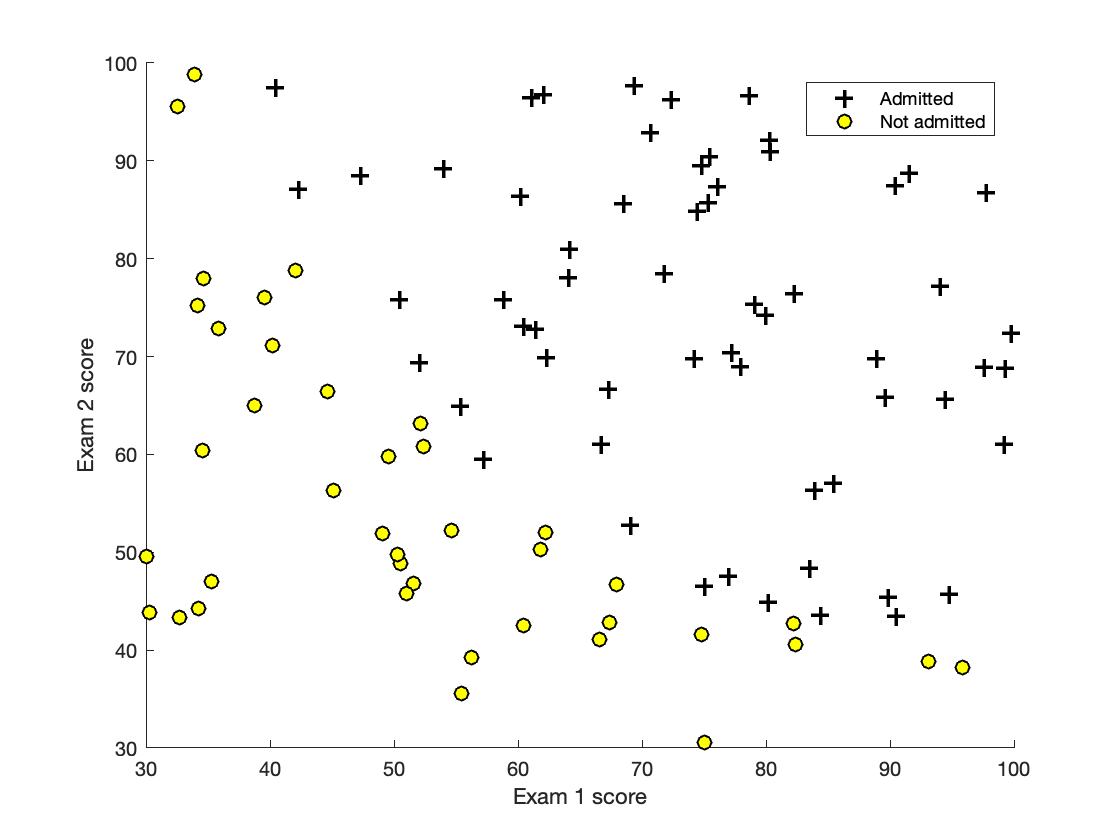


plotData(X, y);

% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;


fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


## ============ Part 2: Compute Cost and Gradient ============

`In this part of the exercise, you will implement the cost and gradient`

`for logistic regression. You neeed to complete the code in `

`costFunction.m`

%  Setup the data matrix appropriately, and add ones for the intercept term
[m, n] = size(X);

% Add intercept term to x and X_test
X = [ones(m, 1) X];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000



fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


fprintf('Gradient at initial theta (zeros): \n');

Gradient at initial theta (zeros): 


fprintf(' %f \n', grad);

 -0.100000 
 -12.009217 
 -11.262842 



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


## ============= Part 3: Optimizing using fminunc =============

`In this exercise, you will use a built-in function (fminunc) to find the`

`optimal parameters theta.`

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = ...
	fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


g =     0.6340
    0.1369
    0.5583
    0.8452
    0.8019
    0.3397
    0.9171
    0.3484
    0.8948
    0.3519


g =     0.6340
    0.1369
    0.5583
    0.8452
    0.8019
    0.3397
    0.9171
    0.3484
    0.8948
    0.3519


g =     0.6340
    0.1369
    0.5583
    0.8452
    0.8019
    0.3397
    0.9171
    0.3484
    0.8948
    0.3519


g =     0.6340
    0.1369
    0.5583
    0.8452
    0.8019
    0.3397
    0.9171
    0.3484
    0.8948
    0.3519


g =     0.3312
    0.0821
    0.2998
    0.7627
    0.8605
    0.2676
    0.8399
    0.5876
    0.8966
    0.6865


g =     0.3312
    0.0821
    0.2998
    0.7627
    0.8605
    0.2676
    0.8399
    0.5876
    0.8966
    0.6865


g =     0.3312
    0.0821
    0.2998
    0.7627
    0.8605
    0.2676
    0.8399
    0.5876
    0.8966
    0.6865


g =     0.3312
    0.0821
    0.2998
    0.7627
    0.8605
    0.2676
    0.8399
    0.5876
    0.8966
    0.6865


g =     0.2088
    0.0389
    0.1896
    0.7730
    0.9137
    0.1992
    0.8524
    0.6786
    0.9334
    0.8055


g =     0.2088
    0.0389
    0.1896
    0.7730
    0.9137
    0.1992
    0.8524
    0.6786
    0.9334
    0.8055


g =     0.2088
    0.0389
    0.1896
    0.7730
    0.9137
    0.1992
    0.8524
    0.6786
    0.9334
    0.8055


g =     0.2088
    0.0389
    0.1896
    0.7730
    0.9137
    0.1992
    0.8524
    0.6786
    0.9334
    0.8055


g =     0.3528
    0.0473
    0.3008
    0.8293
    0.8945
    0.2202
    0.9066
    0.5233
    0.9366
    0.6278


g =     0.3528
    0.0473
    0.3008
    0.8293
    0.8945
    0.2202
    0.9066
    0.5233
    0.9366
    0.6278


g =     0.3528
    0.0473
    0.3008
    0.8293
    0.8945
    0.2202
    0.9066
    0.5233
    0.9366
    0.6278


g =     0.3528
    0.0473
    0.3008
    0.8293
    0.8945
    0.2202
    0.9066
    0.5233
    0.9366
    0.6278


g =     0.1688
    0.0057
    0.1283
    0.8889
    0.9627
    0.0868
    0.9571
    0.5485
    0.9821
    0.7309


g =     0.1688
    0.0057
    0.1283
    0.8889
    0.9627
    0.0868
    0.9571
    0.5485
    0.9821
    0.7309


g =     0.1688
    0.0057
    0.1283
    0.8889
    0.9627
    0.0868
    0.9571
    0.5485
    0.9821
    0.7309


g =     0.1688
    0.0057
    0.1283
    0.8889
    0.9627
    0.0868
    0.9571
    0.5485
    0.9821
    0.7309


g =     0.2488
    0.0064
    0.1827
    0.9202
    0.9651
    0.0984
    0.9730
    0.4892
    0.9858
    0.6557


g =     0.2488
    0.0064
    0.1827
    0.9202
    0.9651
    0.0984
    0.9730
    0.4892
    0.9858
    0.6557


g =     0.2488
    0.0064
    0.1827
    0.9202
    0.9651
    0.0984
    0.9730
    0.4892
    0.9858
    0.6557


g =     0.2488
    0.0064
    0.1827
    0.9202
    0.9651
    0.0984
    0.9730
    0.4892
    0.9858
    0.6557


g =     0.1272
    0.0015
    0.0873
    0.9344
    0.9829
    0.0489
    0.9815
    0.5347
    0.9936
    0.7540


g =     0.1272
    0.0015
    0.0873
    0.9344
    0.9829
    0.0489
    0.9815
    0.5347
    0.9936
    0.7540


g =     0.1272
    0.0015
    0.0873
    0.9344
    0.9829
    0.0489
    0.9815
    0.5347
    0.9936
    0.7540


g =     0.1272
    0.0015
    0.0873
    0.9344
    0.9829
    0.0489
    0.9815
    0.5347
    0.9936
    0.7540


g =     0.1878
    0.0019
    0.1256
    0.9496
    0.9830
    0.0581
    0.9870
    0.4868
    0.9944
    0.6925


g =     0.1878
    0.0019
    0.1256
    0.9496
    0.9830
    0.0581
    0.9870
    0.4868
    0.9944
    0.6925


g =     0.1878
    0.0019
    0.1256
    0.9496
    0.9830
    0.0581
    0.9870
    0.4868
    0.9944
    0.6925


g =     0.1878
    0.0019
    0.1256
    0.9496
    0.9830
    0.0581
    0.9870
    0.4868
    0.9944
    0.6925


g =     0.1621
    0.0016
    0.1083
    0.9450
    0.9828
    0.0521
    0.9856
    0.4883
    0.9942
    0.7018


g =     0.1621
    0.0016
    0.1083
    0.9450
    0.9828
    0.0521
    0.9856
    0.4883
    0.9942
    0.7018


g =     0.1621
    0.0016
    0.1083
    0.9450
    0.9828
    0.0521
    0.9856
    0.4883
    0.9942
    0.7018


g =     0.1621
    0.0016
    0.1083
    0.9450
    0.9828
    0.0521
    0.9856
    0.4883
    0.9942
    0.7018


g =     0.2036
    0.0011
    0.1274
    0.9651
    0.9872
    0.0467
    0.9926
    0.4260
    0.9965
    0.6370


g =     0.2036
    0.0011
    0.1274
    0.9651
    0.9872
    0.0467
    0.9926
    0.4260
    0.9965
    0.6370


g =     0.2036
    0.0011
    0.1274
    0.9651
    0.9872
    0.0467
    0.9926
    0.4260
    0.9965
    0.6370


g =     0.2036
    0.0011
    0.1274
    0.9651
    0.9872
    0.0467
    0.9926
    0.4260
    0.9965
    0.6370


g =     0.1657
    0.0010
    0.1050
    0.9609
    0.9880
    0.0436
    0.9913
    0.4713
    0.9965
    0.6955


g =     0.1657
    0.0010
    0.1050
    0.9609
    0.9880
    0.0436
    0.9913
    0.4713
    0.9965
    0.6955


g =     0.1657
    0.0010
    0.1050
    0.9609
    0.9880
    0.0436
    0.9913
    0.4713
    0.9965
    0.6955


g =     0.1657
    0.0010
    0.1050
    0.9609
    0.9880
    0.0436
    0.9913
    0.4713
    0.9965
    0.6955


g =     0.1890
    0.0007
    0.1130
    0.9726
    0.9906
    0.0377
    0.9949
    0.4179
    0.9977
    0.6433


g =     0.1890
    0.0007
    0.1130
    0.9726
    0.9906
    0.0377
    0.9949
    0.4179
    0.9977
    0.6433


g =     0.1890
    0.0007
    0.1130
    0.9726
    0.9906
    0.0377
    0.9949
    0.4179
    0.9977
    0.6433


g =     0.1890
    0.0007
    0.1130
    0.9726
    0.9906
    0.0377
    0.9949
    0.4179
    0.9977
    0.6433


g =     0.1539
    0.0006
    0.0935
    0.9688
    0.9910
    0.0355
    0.9938
    0.4615
    0.9976
    0.6989


g =     0.1539
    0.0006
    0.0935
    0.9688
    0.9910
    0.0355
    0.9938
    0.4615
    0.9976
    0.6989


g =     0.1539
    0.0006
    0.0935
    0.9688
    0.9910
    0.0355
    0.9938
    0.4615
    0.9976
    0.6989


g =     0.1539
    0.0006
    0.0935
    0.9688
    0.9910
    0.0355
    0.9938
    0.4615
    0.9976
    0.6989


g =     0.1685
    0.0003
    0.0948
    0.9802
    0.9939
    0.0280
    0.9969
    0.4099
    0.9987
    0.6555


g =     0.1685
    0.0003
    0.0948
    0.9802
    0.9939
    0.0280
    0.9969
    0.4099
    0.9987
    0.6555


g =     0.1685
    0.0003
    0.0948
    0.9802
    0.9939
    0.0280
    0.9969
    0.4099
    0.9987
    0.6555


g =     0.1685
    0.0003
    0.0948
    0.9802
    0.9939
    0.0280
    0.9969
    0.4099
    0.9987
    0.6555


g =     0.1350
    0.0003
    0.0772
    0.9769
    0.9941
    0.0261
    0.9961
    0.4506
    0.9986
    0.7076


g =     0.1350
    0.0003
    0.0772
    0.9769
    0.9941
    0.0261
    0.9961
    0.4506
    0.9986
    0.7076


g =     0.1350
    0.0003
    0.0772
    0.9769
    0.9941
    0.0261
    0.9961
    0.4506
    0.9986
    0.7076


g =     0.1350
    0.0003
    0.0772
    0.9769
    0.9941
    0.0261
    0.9961
    0.4506
    0.9986
    0.7076


g =     0.1470
    0.0002
    0.0802
    0.9828
    0.9953
    0.0231
    0.9975
    0.4179
    0.9990
    0.6791


g =     0.1470
    0.0002
    0.0802
    0.9828
    0.9953
    0.0231
    0.9975
    0.4179
    0.9990
    0.6791


g =     0.1470
    0.0002
    0.0802
    0.9828
    0.9953
    0.0231
    0.9975
    0.4179
    0.9990
    0.6791


g =     0.1470
    0.0002
    0.0802
    0.9828
    0.9953
    0.0231
    0.9975
    0.4179
    0.9990
    0.6791


g =     0.1247
    0.0002
    0.0689
    0.9807
    0.9953
    0.0218
    0.9970
    0.4450
    0.9990
    0.7134


g =     0.1247
    0.0002
    0.0689
    0.9807
    0.9953
    0.0218
    0.9970
    0.4450
    0.9990
    0.7134


g =     0.1247
    0.0002
    0.0689
    0.9807
    0.9953
    0.0218
    0.9970
    0.4450
    0.9990
    0.7134


g =     0.1247
    0.0002
    0.0689
    0.9807
    0.9953
    0.0218
    0.9970
    0.4450
    0.9990
    0.7134


g =     0.1340
    0.0002
    0.0717
    0.9842
    0.9960
    0.0203
    0.9978
    0.4214
    0.9992
    0.6922


g =     0.1340
    0.0002
    0.0717
    0.9842
    0.9960
    0.0203
    0.9978
    0.4214
    0.9992
    0.6922


g =     0.1340
    0.0002
    0.0717
    0.9842
    0.9960
    0.0203
    0.9978
    0.4214
    0.9992
    0.6922


g =     0.1340
    0.0002
    0.0717
    0.9842
    0.9960
    0.0203
    0.9978
    0.4214
    0.9992
    0.6922


g =     0.1185
    0.0002
    0.0640
    0.9828
    0.9960
    0.0194
    0.9975
    0.4414
    0.9992
    0.7172


g =     0.1185
    0.0002
    0.0640
    0.9828
    0.9960
    0.0194
    0.9975
    0.4414
    0.9992
    0.7172


g =     0.1185
    0.0002
    0.0640
    0.9828
    0.9960
    0.0194
    0.9975
    0.4414
    0.9992
    0.7172


g =     0.1185
    0.0002
    0.0640
    0.9828
    0.9960
    0.0194
    0.9975
    0.4414
    0.9992
    0.7172


g =     0.1258
    0.0001
    0.0662
    0.9854
    0.9965
    0.0183
    0.9980
    0.4223
    0.9993
    0.7000


g =     0.1258
    0.0001
    0.0662
    0.9854
    0.9965
    0.0183
    0.9980
    0.4223
    0.9993
    0.7000


g =     0.1258
    0.0001
    0.0662
    0.9854
    0.9965
    0.0183
    0.9980
    0.4223
    0.9993
    0.7000


g =     0.1258
    0.0001
    0.0662
    0.9854
    0.9965
    0.0183
    0.9980
    0.4223
    0.9993
    0.7000


g =     0.1137
    0.0001
    0.0604
    0.9843
    0.9965
    0.0177
    0.9978
    0.4386
    0.9993
    0.7201


g =     0.1137
    0.0001
    0.0604
    0.9843
    0.9965
    0.0177
    0.9978
    0.4386
    0.9993
    0.7201


g =     0.1137
    0.0001
    0.0604
    0.9843
    0.9965
    0.0177
    0.9978
    0.4386
    0.9993
    0.7201


g =     0.1137
    0.0001
    0.0604
    0.9843
    0.9965
    0.0177
    0.9978
    0.4386
    0.9993
    0.7201


g =     0.1197
    0.0001
    0.0622
    0.9862
    0.9968
    0.0169
    0.9982
    0.4227
    0.9994
    0.7059


g =     0.1197
    0.0001
    0.0622
    0.9862
    0.9968
    0.0169
    0.9982
    0.4227
    0.9994
    0.7059


g =     0.1197
    0.0001
    0.0622
    0.9862
    0.9968
    0.0169
    0.9982
    0.4227
    0.9994
    0.7059


g =     0.1197
    0.0001
    0.0622
    0.9862
    0.9968
    0.0169
    0.9982
    0.4227
    0.9994
    0.7059


g =     0.1100
    0.0001
    0.0575
    0.9854
    0.9968
    0.0165
    0.9981
    0.4363
    0.9994
    0.7225


g =     0.1100
    0.0001
    0.0575
    0.9854
    0.9968
    0.0165
    0.9981
    0.4363
    0.9994
    0.7225


g =     0.1100
    0.0001
    0.0575
    0.9854
    0.9968
    0.0165
    0.9981
    0.4363
    0.9994
    0.7225


g =     0.1100
    0.0001
    0.0575
    0.9854
    0.9968
    0.0165
    0.9981
    0.4363
    0.9994
    0.7225


g =     0.1149
    0.0001
    0.0590
    0.9869
    0.9971
    0.0158
    0.9984
    0.4230
    0.9995
    0.7106


g =     0.1149
    0.0001
    0.0590
    0.9869
    0.9971
    0.0158
    0.9984
    0.4230
    0.9995
    0.7106


g =     0.1149
    0.0001
    0.0590
    0.9869
    0.9971
    0.0158
    0.9984
    0.4230
    0.9995
    0.7106


g =     0.1149
    0.0001
    0.0590
    0.9869
    0.9971
    0.0158
    0.9984
    0.4230
    0.9995
    0.7106


g =     0.1070
    0.0001
    0.0553
    0.9863
    0.9971
    0.0155
    0.9982
    0.4343
    0.9995
    0.7244


g =     0.1070
    0.0001
    0.0553
    0.9863
    0.9971
    0.0155
    0.9982
    0.4343
    0.9995
    0.7244


g =     0.1070
    0.0001
    0.0553
    0.9863
    0.9971
    0.0155
    0.9982
    0.4343
    0.9995
    0.7244


g =     0.1070
    0.0001
    0.0553
    0.9863
    0.9971
    0.0155
    0.9982
    0.4343
    0.9995
    0.7244


g =     0.1110
    0.0001
    0.0565
    0.9875
    0.9973
    0.0150
    0.9985
    0.4232
    0.9995
    0.7144


g =     0.1110
    0.0001
    0.0565
    0.9875
    0.9973
    0.0150
    0.9985
    0.4232
    0.9995
    0.7144


g =     0.1110
    0.0001
    0.0565
    0.9875
    0.9973
    0.0150
    0.9985
    0.4232
    0.9995
    0.7144


g =     0.1110
    0.0001
    0.0565
    0.9875
    0.9973
    0.0150
    0.9985
    0.4232
    0.9995
    0.7144


g =     0.1046
    0.0001
    0.0535
    0.9870
    0.9973
    0.0147
    0.9984
    0.4327
    0.9995
    0.7260


g =     0.1046
    0.0001
    0.0535
    0.9870
    0.9973
    0.0147
    0.9984
    0.4327
    0.9995
    0.7260


g =     0.1046
    0.0001
    0.0535
    0.9870
    0.9973
    0.0147
    0.9984
    0.4327
    0.9995
    0.7260


g =     0.1046
    0.0001
    0.0535
    0.9870
    0.9973
    0.0147
    0.9984
    0.4327
    0.9995
    0.7260


g =     0.1079
    0.0001
    0.0545
    0.9880
    0.9974
    0.0143
    0.9985
    0.4233
    0.9995
    0.7176


g =     0.1079
    0.0001
    0.0545
    0.9880
    0.9974
    0.0143
    0.9985
    0.4233
    0.9995
    0.7176


g =     0.1079
    0.0001
    0.0545
    0.9880
    0.9974
    0.0143
    0.9985
    0.4233
    0.9995
    0.7176


g =     0.1079
    0.0001
    0.0545
    0.9880
    0.9974
    0.0143
    0.9985
    0.4233
    0.9995
    0.7176


g =     0.1025
    0.0001
    0.0520
    0.9875
    0.9974
    0.0141
    0.9985
    0.4314
    0.9995
    0.7274


g =     0.1025
    0.0001
    0.0520
    0.9875
    0.9974
    0.0141
    0.9985
    0.4314
    0.9995
    0.7274


g =     0.1025
    0.0001
    0.0520
    0.9875
    0.9974
    0.0141
    0.9985
    0.4314
    0.9995
    0.7274


g =     0.1025
    0.0001
    0.0520
    0.9875
    0.9974
    0.0141
    0.9985
    0.4314
    0.9995
    0.7274


g =     0.1054
    0.0001
    0.0529
    0.9883
    0.9975
    0.0137
    0.9986
    0.4233
    0.9996
    0.7202


g =     0.1054
    0.0001
    0.0529
    0.9883
    0.9975
    0.0137
    0.9986
    0.4233
    0.9996
    0.7202


g =     0.1054
    0.0001
    0.0529
    0.9883
    0.9975
    0.0137
    0.9986
    0.4233
    0.9996
    0.7202


g =     0.1054
    0.0001
    0.0529
    0.9883
    0.9975
    0.0137
    0.9986
    0.4233
    0.9996
    0.7202


g =     0.1009
    0.0001
    0.0508
    0.9880
    0.9976
    0.0136
    0.9986
    0.4302
    0.9996
    0.7285


g =     0.1009
    0.0001
    0.0508
    0.9880
    0.9976
    0.0136
    0.9986
    0.4302
    0.9996
    0.7285


g =     0.1009
    0.0001
    0.0508
    0.9880
    0.9976
    0.0136
    0.9986
    0.4302
    0.9996
    0.7285


g =     0.1009
    0.0001
    0.0508
    0.9880
    0.9976
    0.0136
    0.9986
    0.4302
    0.9996
    0.7285


g =     0.1032
    0.0001
    0.0515
    0.9887
    0.9977
    0.0133
    0.9987
    0.4234
    0.9996
    0.7224


g =     0.1032
    0.0001
    0.0515
    0.9887
    0.9977
    0.0133
    0.9987
    0.4234
    0.9996
    0.7224


g =     0.1032
    0.0001
    0.0515
    0.9887
    0.9977
    0.0133
    0.9987
    0.4234
    0.9996
    0.7224


g =     0.1032
    0.0001
    0.0515
    0.9887
    0.9977
    0.0133
    0.9987
    0.4234
    0.9996
    0.7224


g =     0.0995
    0.0001
    0.0498
    0.9884
    0.9977
    0.0131
    0.9986
    0.4293
    0.9996
    0.7295


g =     0.0995
    0.0001
    0.0498
    0.9884
    0.9977
    0.0131
    0.9986
    0.4293
    0.9996
    0.7295


g =     0.0995
    0.0001
    0.0498
    0.9884
    0.9977
    0.0131
    0.9986
    0.4293
    0.9996
    0.7295


g =     0.0995
    0.0001
    0.0498
    0.9884
    0.9977
    0.0131
    0.9986
    0.4293
    0.9996
    0.7295


g =     0.1015
    0.0001
    0.0504
    0.9889
    0.9977
    0.0129
    0.9987
    0.4234
    0.9996
    0.7242


g =     0.1015
    0.0001
    0.0504
    0.9889
    0.9977
    0.0129
    0.9987
    0.4234
    0.9996
    0.7242


g =     0.1015
    0.0001
    0.0504
    0.9889
    0.9977
    0.0129
    0.9987
    0.4234
    0.9996
    0.7242


g =     0.1015
    0.0001
    0.0504
    0.9889
    0.9977
    0.0129
    0.9987
    0.4234
    0.9996
    0.7242


g =     0.0983
    0.0001
    0.0490
    0.9887
    0.9977
    0.0128
    0.9987
    0.4285
    0.9996
    0.7303


g =     0.0983
    0.0001
    0.0490
    0.9887
    0.9977
    0.0128
    0.9987
    0.4285
    0.9996
    0.7303


g =     0.0983
    0.0001
    0.0490
    0.9887
    0.9977
    0.0128
    0.9987
    0.4285
    0.9996
    0.7303


g =     0.0983
    0.0001
    0.0490
    0.9887
    0.9977
    0.0128
    0.9987
    0.4285
    0.9996
    0.7303


g =     0.1000
    0.0001
    0.0495
    0.9891
    0.9978
    0.0126
    0.9988
    0.4234
    0.9996
    0.7258


g =     0.1000
    0.0001
    0.0495
    0.9891
    0.9978
    0.0126
    0.9988
    0.4234
    0.9996
    0.7258


g =     0.1000
    0.0001
    0.0495
    0.9891
    0.9978
    0.0126
    0.9988
    0.4234
    0.9996
    0.7258


g =     0.1000
    0.0001
    0.0495
    0.9891
    0.9978
    0.0126
    0.9988
    0.4234
    0.9996
    0.7258


g =     0.0973
    0.0001
    0.0483
    0.9889
    0.9978
    0.0125
    0.9987
    0.4277
    0.9996
    0.7310


g =     0.0973
    0.0001
    0.0483
    0.9889
    0.9978
    0.0125
    0.9987
    0.4277
    0.9996
    0.7310


g =     0.0973
    0.0001
    0.0483
    0.9889
    0.9978
    0.0125
    0.9987
    0.4277
    0.9996
    0.7310


g =     0.0973
    0.0001
    0.0483
    0.9889
    0.9978
    0.0125
    0.9987
    0.4277
    0.9996
    0.7310


g =     0.0987
    0.0001
    0.0487
    0.9893
    0.9979
    0.0124
    0.9988
    0.4234
    0.9996
    0.7271


g =     0.0987
    0.0001
    0.0487
    0.9893
    0.9979
    0.0124
    0.9988
    0.4234
    0.9996
    0.7271


g =     0.0987
    0.0001
    0.0487
    0.9893
    0.9979
    0.0124
    0.9988
    0.4234
    0.9996
    0.7271


g =     0.0987
    0.0001
    0.0487
    0.9893
    0.9979
    0.0124
    0.9988
    0.4234
    0.9996
    0.7271


g =     0.0964
    0.0001
    0.0476
    0.9891
    0.9979
    0.0123
    0.9988
    0.4271
    0.9996
    0.7316


g =     0.0964
    0.0001
    0.0476
    0.9891
    0.9979
    0.0123
    0.9988
    0.4271
    0.9996
    0.7316


g =     0.0964
    0.0001
    0.0476
    0.9891
    0.9979
    0.0123
    0.9988
    0.4271
    0.9996
    0.7316


g =     0.0964
    0.0001
    0.0476
    0.9891
    0.9979
    0.0123
    0.9988
    0.4271
    0.9996
    0.7316


g =     0.0977
    0.0001
    0.0480
    0.9895
    0.9979
    0.0121
    0.9988
    0.4234
    0.9997
    0.7282


g =     0.0977
    0.0001
    0.0480
    0.9895
    0.9979
    0.0121
    0.9988
    0.4234
    0.9997
    0.7282


g =     0.0977
    0.0001
    0.0480
    0.9895
    0.9979
    0.0121
    0.9988
    0.4234
    0.9997
    0.7282


g =     0.0977
    0.0001
    0.0480
    0.9895
    0.9979
    0.0121
    0.9988
    0.4234
    0.9997
    0.7282


g =     0.0957
    0.0001
    0.0471
    0.9893
    0.9979
    0.0121
    0.9988
    0.4266
    0.9996
    0.7321


g =     0.0957
    0.0001
    0.0471
    0.9893
    0.9979
    0.0121
    0.9988
    0.4266
    0.9996
    0.7321


g =     0.0957
    0.0001
    0.0471
    0.9893
    0.9979
    0.0121
    0.9988
    0.4266
    0.9996
    0.7321


g =     0.0957
    0.0001
    0.0471
    0.9893
    0.9979
    0.0121
    0.9988
    0.4266
    0.9996
    0.7321


g =     0.0968
    0.0001
    0.0475
    0.9896
    0.9980
    0.0119
    0.9988
    0.4234
    0.9997
    0.7292


g =     0.0968
    0.0001
    0.0475
    0.9896
    0.9980
    0.0119
    0.9988
    0.4234
    0.9997
    0.7292


g =     0.0968
    0.0001
    0.0475
    0.9896
    0.9980
    0.0119
    0.9988
    0.4234
    0.9997
    0.7292


g =     0.0968
    0.0001
    0.0475
    0.9896
    0.9980
    0.0119
    0.9988
    0.4234
    0.9997
    0.7292


g =     0.0950
    0.0001
    0.0467
    0.9895
    0.9980
    0.0119
    0.9988
    0.4262
    0.9997
    0.7325


g =     0.0950
    0.0001
    0.0467
    0.9895
    0.9980
    0.0119
    0.9988
    0.4262
    0.9997
    0.7325


g =     0.0950
    0.0001
    0.0467
    0.9895
    0.9980
    0.0119
    0.9988
    0.4262
    0.9997
    0.7325


g =     0.0950
    0.0001
    0.0467
    0.9895
    0.9980
    0.0119
    0.9988
    0.4262
    0.9997
    0.7325


g =     0.0960
    0.0001
    0.0470
    0.9897
    0.9980
    0.0118
    0.9989
    0.4234
    0.9997
    0.7300


g =     0.0960
    0.0001
    0.0470
    0.9897
    0.9980
    0.0118
    0.9989
    0.4234
    0.9997
    0.7300


g =     0.0960
    0.0001
    0.0470
    0.9897
    0.9980
    0.0118
    0.9989
    0.4234
    0.9997
    0.7300


g =     0.0960
    0.0001
    0.0470
    0.9897
    0.9980
    0.0118
    0.9989
    0.4234
    0.9997
    0.7300


g =     0.0945
    0.0001
    0.0463
    0.9896
    0.9980
    0.0117
    0.9988
    0.4258
    0.9997
    0.7329


g =     0.0945
    0.0001
    0.0463
    0.9896
    0.9980
    0.0117
    0.9988
    0.4258
    0.9997
    0.7329


g =     0.0945
    0.0001
    0.0463
    0.9896
    0.9980
    0.0117
    0.9988
    0.4258
    0.9997
    0.7329


g =     0.0945
    0.0001
    0.0463
    0.9896
    0.9980
    0.0117
    0.9988
    0.4258
    0.9997
    0.7329


g =     0.0953
    0.0000
    0.0466
    0.9898
    0.9980
    0.0117
    0.9989
    0.4233
    0.9997
    0.7307


g =     0.0953
    0.0000
    0.0466
    0.9898
    0.9980
    0.0117
    0.9989
    0.4233
    0.9997
    0.7307


g =     0.0953
    0.0000
    0.0466
    0.9898
    0.9980
    0.0117
    0.9989
    0.4233
    0.9997
    0.7307


g =     0.0953
    0.0000
    0.0466
    0.9898
    0.9980
    0.0117
    0.9989
    0.4233
    0.9997
    0.7307


g =     0.0940
    0.0000
    0.0460
    0.9897
    0.9980
    0.0116
    0.9989
    0.4254
    0.9997
    0.7332


g =     0.0940
    0.0000
    0.0460
    0.9897
    0.9980
    0.0116
    0.9989
    0.4254
    0.9997
    0.7332


g =     0.0940
    0.0000
    0.0460
    0.9897
    0.9980
    0.0116
    0.9989
    0.4254
    0.9997
    0.7332


g =     0.0940
    0.0000
    0.0460
    0.9897
    0.9980
    0.0116
    0.9989
    0.4254
    0.9997
    0.7332


g =     0.0947
    0.0000
    0.0462
    0.9899
    0.9980
    0.0115
    0.9989
    0.4233
    0.9997
    0.7314


g =     0.0947
    0.0000
    0.0462
    0.9899
    0.9980
    0.0115
    0.9989
    0.4233
    0.9997
    0.7314


g =     0.0947
    0.0000
    0.0462
    0.9899
    0.9980
    0.0115
    0.9989
    0.4233
    0.9997
    0.7314


g =     0.0947
    0.0000
    0.0462
    0.9899
    0.9980
    0.0115
    0.9989
    0.4233
    0.9997
    0.7314


g =     0.0937
    0.0000
    0.0457
    0.9898
    0.9980
    0.0115
    0.9989
    0.4252
    0.9997
    0.7335


g =     0.0937
    0.0000
    0.0457
    0.9898
    0.9980
    0.0115
    0.9989
    0.4252
    0.9997
    0.7335


g =     0.0937
    0.0000
    0.0457
    0.9898
    0.9980
    0.0115
    0.9989
    0.4252
    0.9997
    0.7335


g =     0.0937
    0.0000
    0.0457
    0.9898
    0.9980
    0.0115
    0.9989
    0.4252
    0.9997
    0.7335


g =     0.0943
    0.0000
    0.0459
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7319


g =     0.0943
    0.0000
    0.0459
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7319


g =     0.0943
    0.0000
    0.0459
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7319


g =     0.0943
    0.0000
    0.0459
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7319


g =     0.0933
    0.0000
    0.0455
    0.9899
    0.9981
    0.0114
    0.9989
    0.4249
    0.9997
    0.7337


g =     0.0933
    0.0000
    0.0455
    0.9899
    0.9981
    0.0114
    0.9989
    0.4249
    0.9997
    0.7337


g =     0.0933
    0.0000
    0.0455
    0.9899
    0.9981
    0.0114
    0.9989
    0.4249
    0.9997
    0.7337


g =     0.0933
    0.0000
    0.0455
    0.9899
    0.9981
    0.0114
    0.9989
    0.4249
    0.9997
    0.7337


g =     0.0938
    0.0000
    0.0456
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7323


g =     0.0938
    0.0000
    0.0456
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7323


g =     0.0938
    0.0000
    0.0456
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7323


g =     0.0938
    0.0000
    0.0456
    0.9900
    0.9981
    0.0114
    0.9989
    0.4233
    0.9997
    0.7323


g =     0.0930
    0.0000
    0.0453
    0.9900
    0.9981
    0.0113
    0.9989
    0.4247
    0.9997
    0.7340


g =     0.0930
    0.0000
    0.0453
    0.9900
    0.9981
    0.0113
    0.9989
    0.4247
    0.9997
    0.7340


g =     0.0930
    0.0000
    0.0453
    0.9900
    0.9981
    0.0113
    0.9989
    0.4247
    0.9997
    0.7340


g =     0.0930
    0.0000
    0.0453
    0.9900
    0.9981
    0.0113
    0.9989
    0.4247
    0.9997
    0.7340


g =     0.0935
    0.0000
    0.0454
    0.9901
    0.9981
    0.0113
    0.9989
    0.4233
    0.9997
    0.7327


g =     0.0935
    0.0000
    0.0454
    0.9901
    0.9981
    0.0113
    0.9989
    0.4233
    0.9997
    0.7327


g =     0.0935
    0.0000
    0.0454
    0.9901
    0.9981
    0.0113
    0.9989
    0.4233
    0.9997
    0.7327


g =     0.0935
    0.0000
    0.0454
    0.9901
    0.9981
    0.0113
    0.9989
    0.4233
    0.9997
    0.7327


g =     0.0928
    0.0000
    0.0451
    0.9900
    0.9981
    0.0113
    0.9989
    0.4245
    0.9997
    0.7341


g =     0.0928
    0.0000
    0.0451
    0.9900
    0.9981
    0.0113
    0.9989
    0.4245
    0.9997
    0.7341


g =     0.0928
    0.0000
    0.0451
    0.9900
    0.9981
    0.0113
    0.9989
    0.4245
    0.9997
    0.7341


g =     0.0928
    0.0000
    0.0451
    0.9900
    0.9981
    0.0113
    0.9989
    0.4245
    0.9997
    0.7341



Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>




% Print theta to screen
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203506


fprintf('theta: \n');

theta: 


fprintf(' %f \n', theta);

 -24.932758 
 0.204406 
 0.199616 



% Plot Boundary
plotDecisionBoundary(theta, X, y);

% Put some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============== Part 4: Predict and Accuracies ==============

`After learning the parameters, you'll like to use it to predict the outcomes`

`on unseen data. In this part, you will use the logistic regression model`

`to predict the probability that a student with score 45 on exam 1 and `

`score 85 on exam 2 will be admitted.`

`Furthermore, you will compute the training and test set accuracies of `

`our model.`

`Your task is to complete the code in predict.m`

%  Predict probability for a student with score 45 on exam 1 
%  and score 85 on exam 2 

prob = sigmoid([1 45 85] * theta);
fprintf(['For a student with scores 45 and 85, we predict an admission ' ...
         'probability of %f\n\n'], prob);

% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

fprintf('\nProgram paused. Press enter to continue.\n');
pause;